For the previous simulation, there's a concern that the acquisition of PKA sensor I used for simulation does not match the prf I used for the fitting and convolution. Thus I borrowed a dataset from Aditi, of which the prf is collected from recent time and close to the experiment time.

Data: /Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001

prf: /Volumes/yaochen/Active/Pingchuan/prf/prf_InsightBottomGreen_20220628.mat

SimulationName='simulation_lifetime_simulationVSexperiment_20220719';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

cd(savefolder)
mkdir(SimulationName)

filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_lifetime_simulationVSexperiment_20220719/'

cd(filepath)

First I need to load the decay curve of PKA sensor.

'/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat' is used and loaded. Look up table 100 to 200.

spc_openCurves('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat',1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat


Then the prf is loaded and copied to this folder.

cd(filepath)
copyfile /Volumes/yaochen/Active/Pingchuan/prf/prf_InsightBottomGreen_20220628.mat prf_PKA.mat

Error using copyfile
Destination
/Users/pingchuanma/Desktop/ChenLab_Data/simulation_lifetime_simulationVSexperiment_20220719/prf_PKA.mat
is not a folder.
When moving a source folder, the
destination must also be a folder.

load('prf_PKA.mat')
prf_peak_PKA=find(prf==max(prf))

prf_peak_PKA = 38

tau1 fixed at 2.14

tau2 fixed at 0.69

I set the fitting range between 1 and 12.5.

Do the fitting and save.

fitting=spc.fits;
save('fitting_PKA_dpt0','fitting')

p1_PKA=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_PKA = 0.6781

p2_PKA=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_PKA = 0.3219

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.0708

SHG=spc.fits{1,1}.beta6

SHG = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 0.9643

backcorr=spc.fits{1,1}.backCorr

backcorr = 146.7692

% lft_steps(1:10)=0;
% lft_steps(247:256)=0;

lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*spc.lifetimes{1};
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1})

empirical_lft_PKA = 3.8978

samplesize_PKA=sum(spc.lifetimes{1})

samplesize_PKA = 2020773

n_exp_PKA=spc.lifetimes{1};

lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*spc.fits{1,1}.curve';

Arrays have incompatible sizes for
this operation.

Related documentation

empirical_lft_fitting=sum(weight_n_lft)/sum(spc.fits{1,1}.curve)


tau1_PKA=2.14

tau1_PKA = 2.1400

tau2_PKA=0.69

tau2_PKA = 0.6900

PKA_PopulationName='PKA_population_20220719_2'

PKA_PopulationName = 'PKA_population_20220719_2'

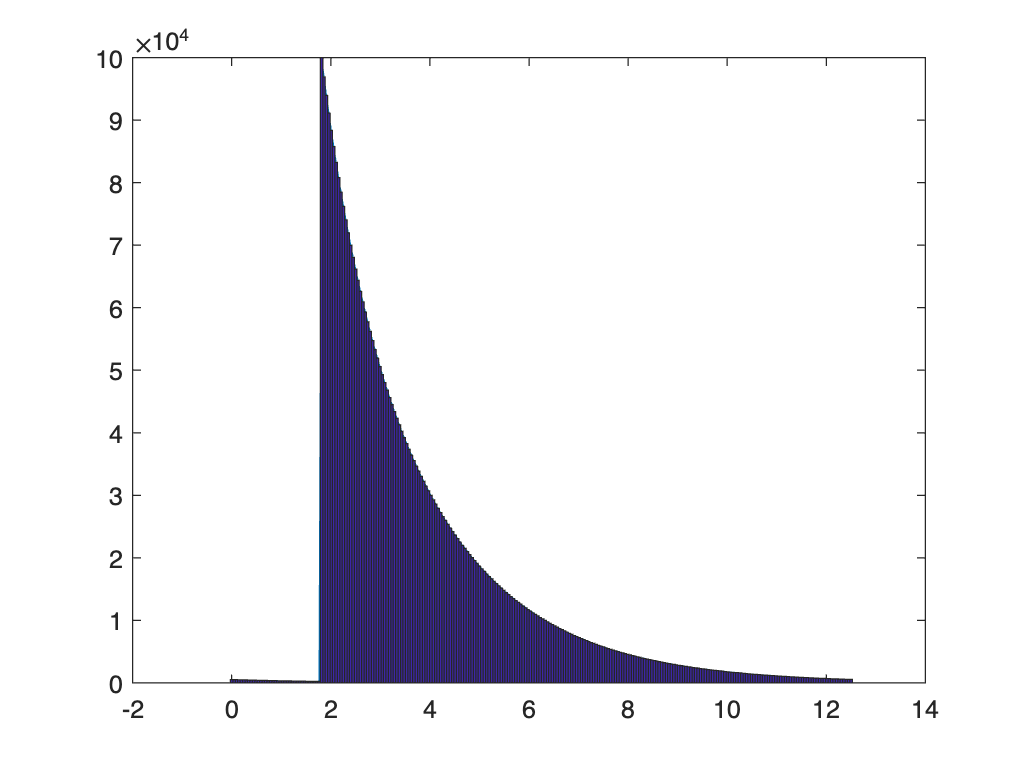

     3873008



GenPop256_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

save('PKA_simulation_parameters_20220719','tau1_PKA','tau2_PKA','p1_PKA','p2_PKA','samplesize_PKA','empirical_lft_PKA','n_exp_PKA','prf_peak_PKA','delta_peak_time')

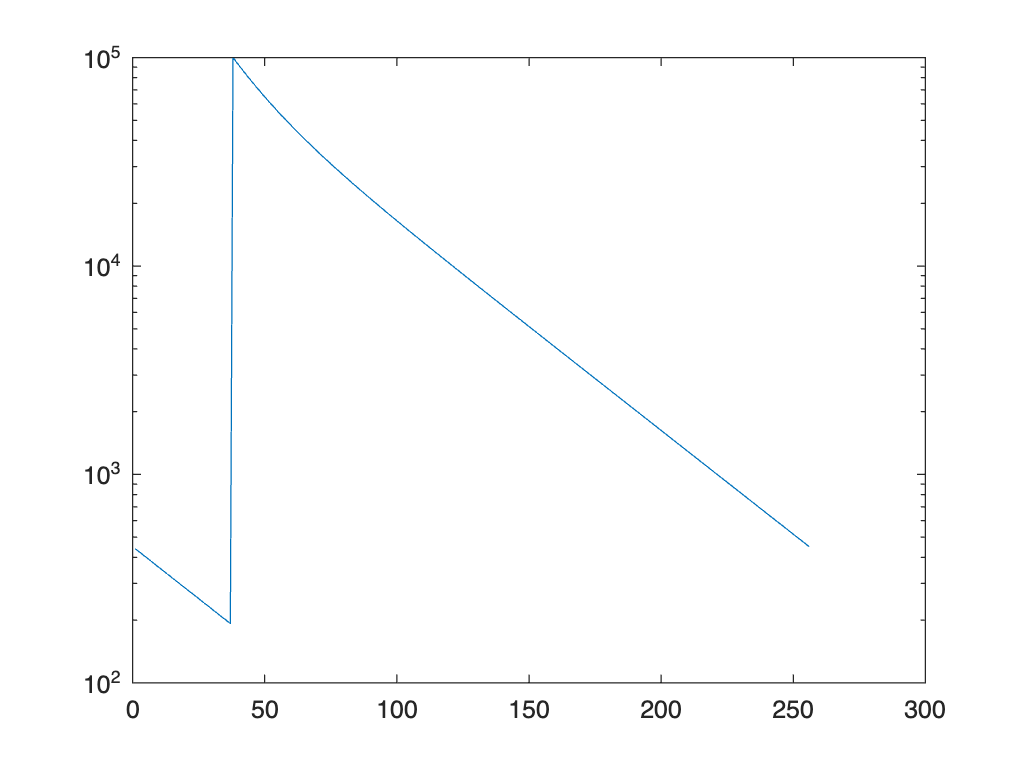

% do the convolution analytically.
% Use two different methods of convolution: one analytical way that I used
% before. Another one the 'conv' function of MATLAB. 'conv' function is
% also the oned used by our fitting algorithm.

load(PKA_PopulationName)
figure
semilogy(counts)

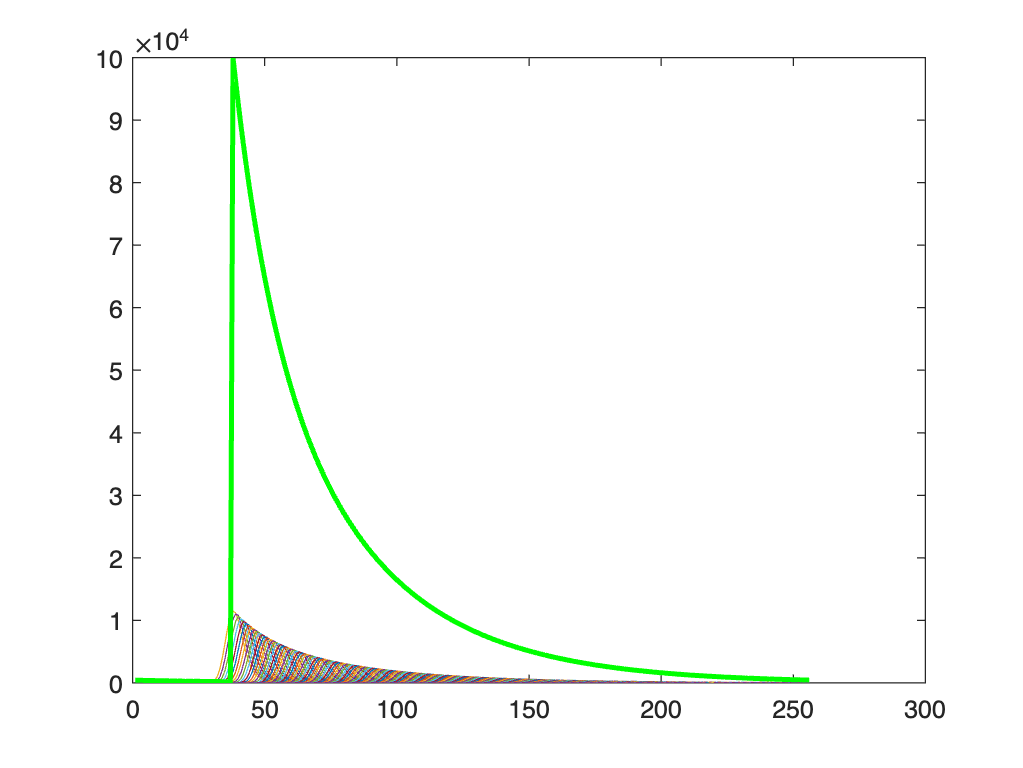

% method 1 analytical. n_c_all is the final histogram after convolution.
x_i=(1:1:256)-prf_peak_PKA;
x=x_i*(12.5/256);
xsim=linspace(0,12.5,256);
[n,xout]=hist(Population, xsim);

    
for i=1:256
    eval(['n_c_',num2str(i),'=zeros(1,256);'])
    n_i = n(i)*prf;
    x_c=x_i+i; 
    
    for j=1:size(x_c,2)
        if x_c(j)<=0
           x_c(j)=x_c(j)+256;  
        end
        
        if x_c(j)>256
            x_c(j)=x_c(j)-256;
        end
        
    end
    eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
end
figure
xlabel('Channels')
ylabel('Photon Count')
for i=1:256
    eval(['plot(n_c_',num2str(i),')'])
    hold on
end
plot(n,'LineWidth',2,'Color','g')
hold on

n_c=zeros(1,256);
for i=1:256
    eval(['this_n=n_c_',num2str(i),';'])
    n_c=[n_c;this_n];
end
n_c_all=sum(n_c);
% eval(['hist_prf2_',num2str(k),'=n_c_all;'])

plot(n_c_all,'LineWidth',2,'Color','r');
hold off


n_c_all_norm=n_c_all/max(n_c_all);

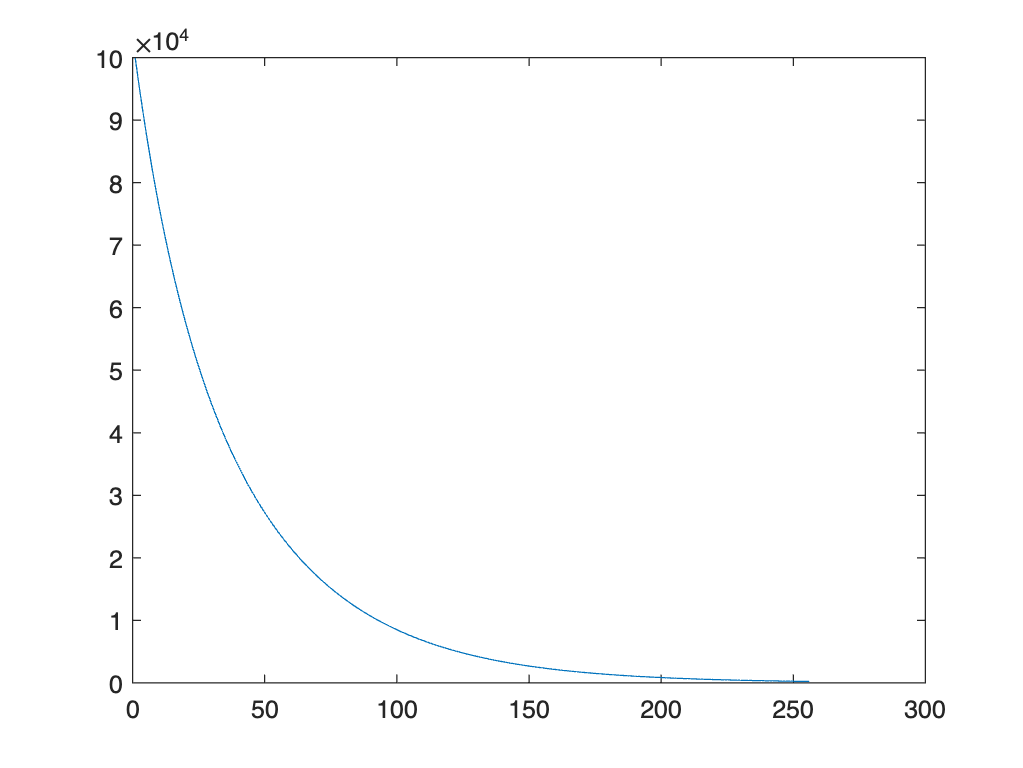

% method 2. 'conv' function
n_to_conv=zeros(1,256);
n_to_conv(1:256-prf_peak_PKA+1)=n(prf_peak_PKA:256);
n_to_conv(256-prf_peak_PKA+2:256)=n(1:prf_peak_PKA-1);
figure
plot(n_to_conv)


conv_n=conv(n_to_conv,prf)

conv_n = 1.0e+04 *

         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0035    0.0099    0.0274    0.0786    0.2115    0.4959    0.9855    1.7124    2.6415    3.6903    4.7405    5.6830    6.4352    6.9713    7.3175    7.5012    7.5609    7.5365    7.4546    7.3366    7.1966    7.0435    6.8830


conv_n1=conv_n(257:length(conv_n));
conv_n_final=conv_n(1:256);
conv_n_final(1:length(conv_n1))=conv_n(1:length(conv_n1))+conv_n1;


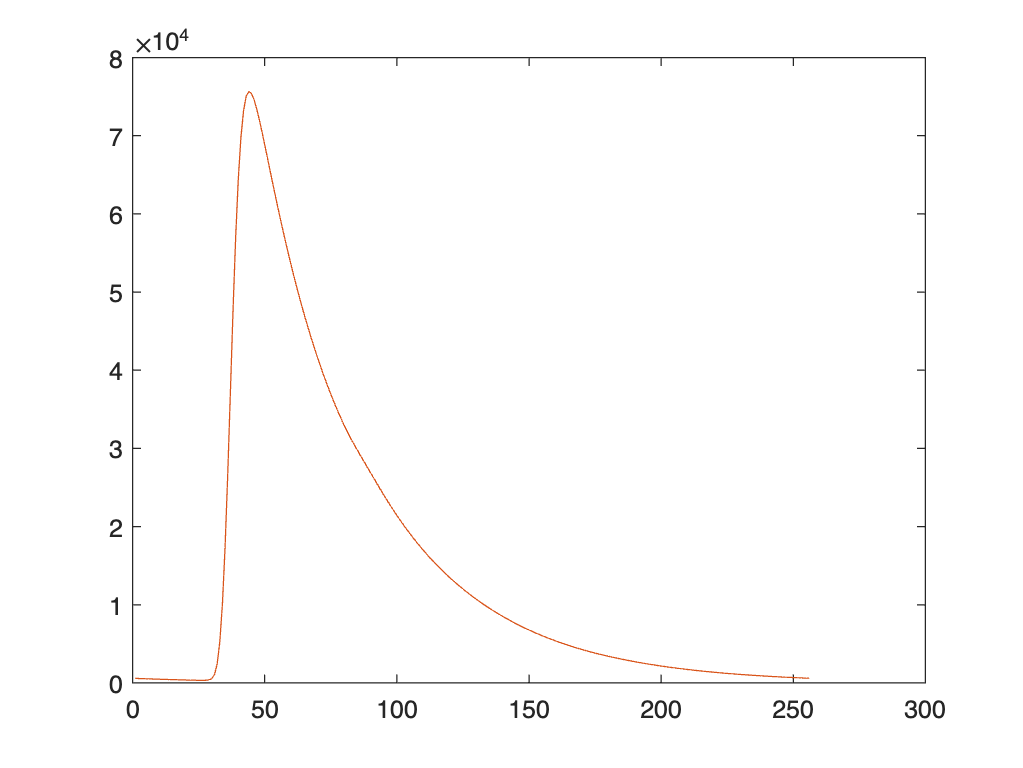


figure
plot(conv_n_final)
hold on
plot(n_c_all)


% These two convolution method gives exactly the same result


% now do the simulation from the population.
% before that define the autofluorescence first.
copyfile /Volumes/yaochen/Active/Pingchuan/simulation/AutoFluo0917.mat autofluorescence.mat


mkdir([filepath,'/PKA_sensoronly_0719_2/']);

AF=0; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach_noauto(samplesize_PKA,0,AF,prf_peak_PKA,PKA_PopulationName, 'prf_PKA.mat', 'autofluorescence.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/PKA_sensoronly_0719_2/',num2str(j)];
    save(samplename,'n','xout');
end


chan=1;
lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*n_c_all;
empirical_lft_analytical=sum(weight_n_lft)/sum(n_c_all)

empirical_lft_analytical = 3.8785


    cd([filepath,'/PKA_sensoronly_0719/']);
    matfiles = dir('*.mat');
    
    p=[];
    TauTrunc=[];
    chi2=[];
    avgTau=[];
    emp_lft=[];
    emp_lftTrunc=[];
    offsets=[];
    deltapeaktimes=[];
    back_corrections=[];
    
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        n=n+backcorr;
        
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*n;
%         empirical_lft=sum(weight_n_lft)/sum(n)+(figureoffset-spc.switchess{1,1}.figOffset); % prf peak at 53. 53*12.5/256=2.5879
        empirical_lft=sum(weight_n_lft)/sum(n);

        p(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2(j)=spc.fits{chan}.redchisq; %chi2
        avgTau(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft(j)=empirical_lft; % empirical lft
        emp_lftTrunc(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
        offsets(j)=spc.switchess{1,1}.figOffset;
        deltapeaktimes(j)=spc.fits{1,1}.beta5;
        back_corrections(j)=spc.fits{1,1}.backCorr;
    end

fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction

load('PKA_simulation_parameters_20220719.mat')
delta_peak_time

delta_peak_time = -0.0708

emp_lft_correction=emp_lft-delta_peak_time;

% add SHG term and generate a new population.
SHG_ratio=SHG/samplesize_PKA

SHG_ratio = 0.0238

PKA_PopulationName_SHG='PKA_population_SHG_20220719'

PKA_PopulationName_SHG = 'PKA_population_SHG_20220719'

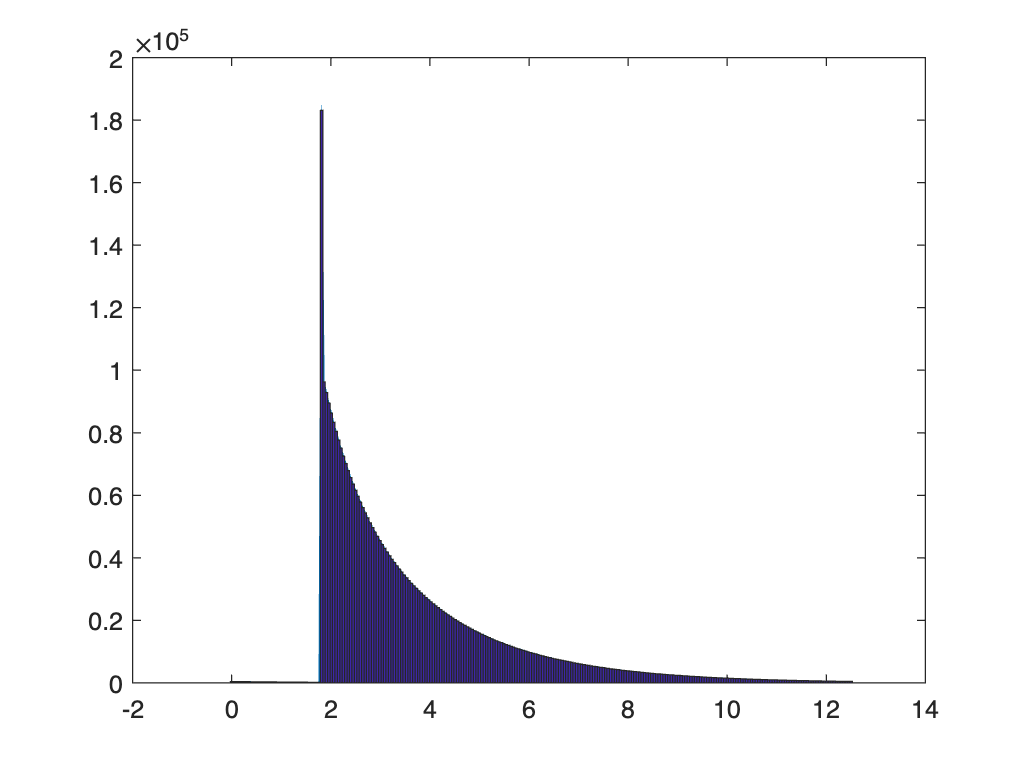

     3578601



GenPop256_Ach_SHG(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName_SHG,prf_peak_PKA,SHG_ratio)

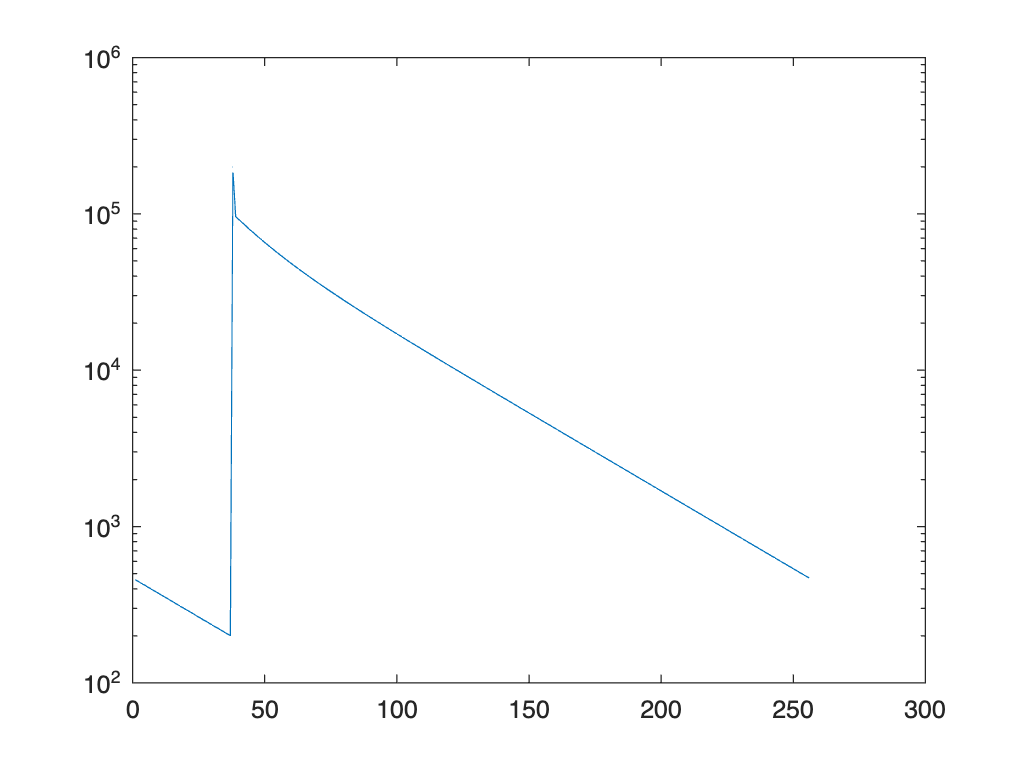

load(PKA_PopulationName_SHG)
figure
semilogy(counts)


mkdir([filepath,'/PKA_sensoronly_0719/']);

AF=0; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach_noauto(samplesize_PKA,0,AF,prf_peak_PKA,PKA_PopulationName, 'prf_PKA.mat', 'autofluorescence.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/PKA_sensoronly_0719/',num2str(j)];
    save(samplename,'n','xout');
end

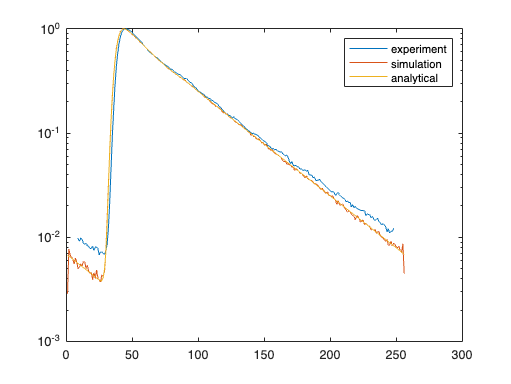

n_exp_PKA_norm=n_exp_PKA/max(n_exp_PKA);
load([filepath,'/PKA_sensoronly_0719/1.mat'])
n_sim_norm=n/max(n);

figure
semilogy(n_exp_PKA_norm)
hold on
semilogy(n_sim_norm)
hold on
semilogy(n_c_all_norm)
legend('experiment','simulation','analytical')

offsets_corr=offsets-figureoffset;
deltapeaktimes_corr=deltapeaktimes-delta_peak_time;
emp_lft_corr=emp_lft+deltapeaktimes_corr;
% emp_lft_corr